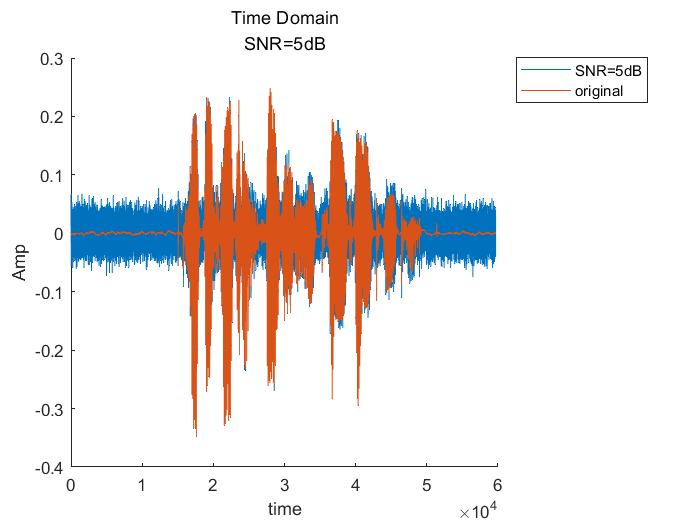

clear;clc;
[y, fs] = audioread("mhint_01_01.wav");
%add white Gaussian noise to the signal at 0 and 5dB SNR
s_5 = awgn(y, 5, 'measured', 'dB');
s_0 = awgn(y, 0, 'measured', 'dB');
%equalize the energy of noisy speech to that of clean speech
s_5 = s_5 * norm(y) / norm(s_5);
s_0 = s_0 * norm(y) / norm(s_0);

audiowrite("mhint_01_01_5db.wav", s_5, fs);
audiowrite("mhint_01_01_0db.wav", s_5, fs);

figure, hold on
   plot(s_5), plot(y);
   legend("SNR=5dB", "original", 'Location','bestoutside');
   xlabel("time"), ylabel("Amp"), title("Time Domain","SNR=5dB");
hold off

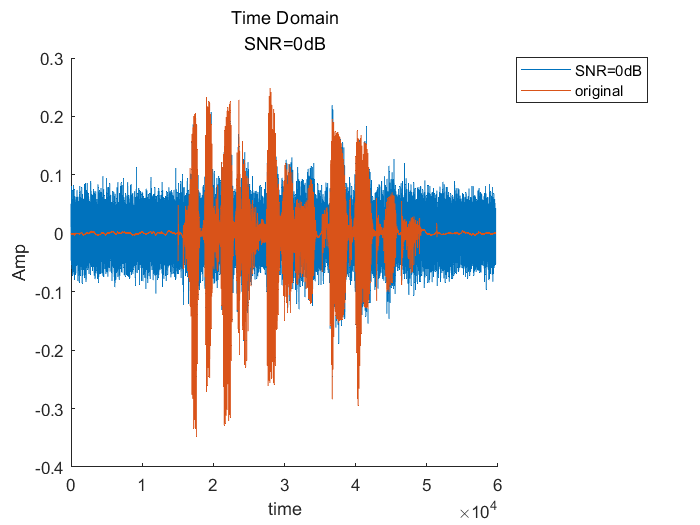


figure, hold on
   plot(s_0), plot(y);
   legend("SNR=0dB", "original", Location="bestoutside");
   xlabel("time"), ylabel("Amp"), title("Time Domain","SNR=0dB");
hold off